% Define the folder containing the videos
videoFolder = './videos';

videoFiles = dir(fullfile(videoFolder));
shot_fps = 480;

times_list = {};

Results for single videos

videoFile = '.\videos\VID_20240610_174337.mp4'

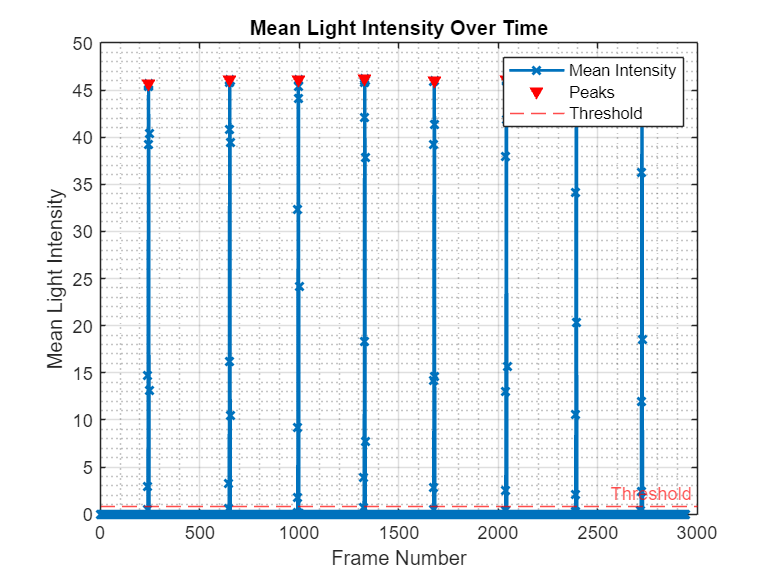

shutter_speed = 0.0187

num_exposures = 8

exposure_time_str = '1/53'

videoFile = '.\videos\VID_20240610_174411.mp4'

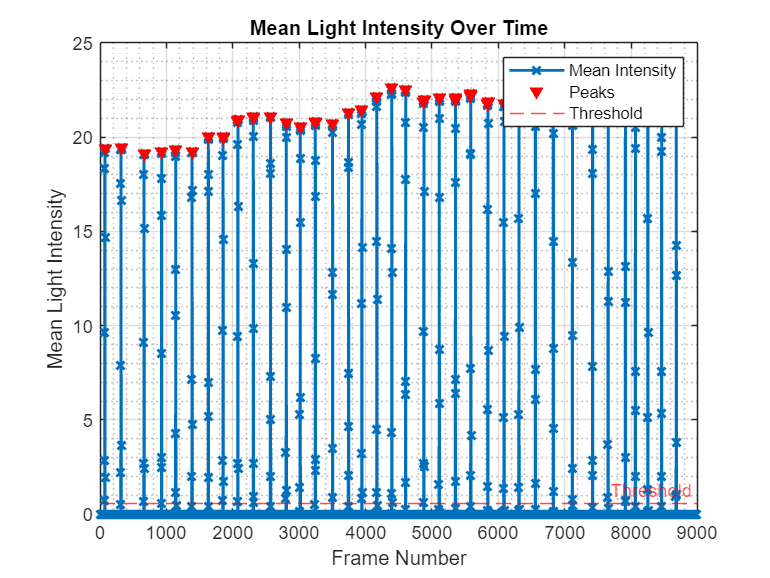

shutter_speed = 0.0147

num_exposures = 49

exposure_time_str = '1/68'

videoFile = '.\videos\brownie_shutter_480fps.mp4'

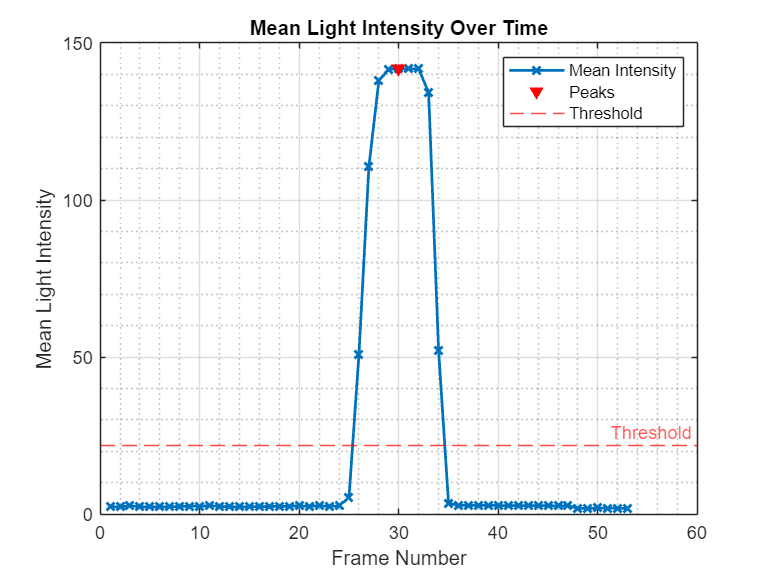

shutter_speed = 0.0187

num_exposures = 1

exposure_time_str = '1/53'

videoFile = '.\videos\brownie_shutter_480fps_2.mp4'

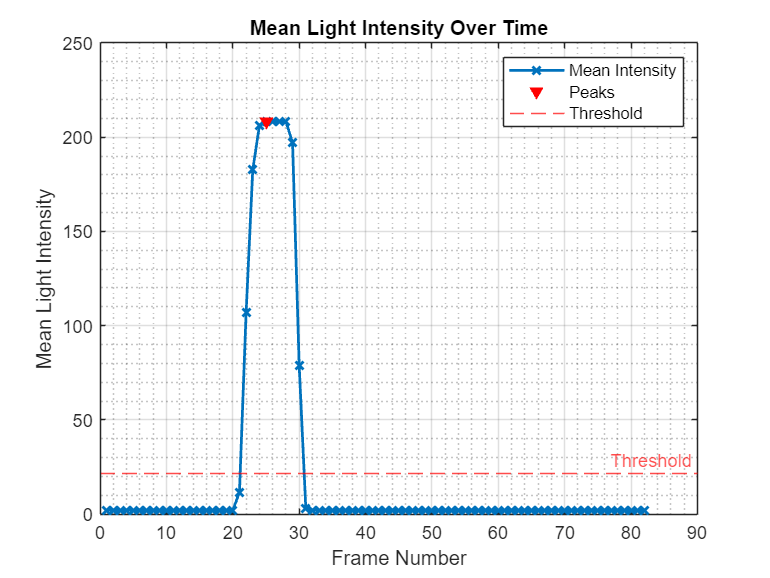

shutter_speed = 0.0187

num_exposures = 1

exposure_time_str = '1/53'

for i=3:length(videoFiles)
    % Get the full path of the video file
    videoFile = fullfile(videoFolder, videoFiles(i).name)
    
    % Display the current video file being processed
    %fprintf('Processing video: %s\n', videoFile);
    
    % Create VideoReader object
    video = VideoReader(videoFile);
    
    % Calculate shutter speed for the current video
    [shutter_speed, num_exposures] = calculate_shutter_speed(video, shot_fps)

    times_list{end+1} = shutter_speed;

    % Convert shutter speed to 1/n format
    if shutter_speed > 0
        exposure_time_n = round(1 / shutter_speed);
        exposure_time_str = ['1/' num2str(exposure_time_n)]
    else
        exposure_time_str = 'N/A'
    end
end

Mean results for all videos

mean_shutter_speed = mean(cell2mat(times_list))

mean_shutter_speed = 0.0177

    % Convert mean_shutter_speed_sec to 1/n format
    if mean_shutter_speed > 0
        mean_shutter = round(1 / mean_shutter_speed);
        mean_exposure_time_str = ['1/' num2str(mean_shutter)]
    else
        mean_exposure_time_str = 'N/A'
    end

mean_exposure_time_str = '1/56'